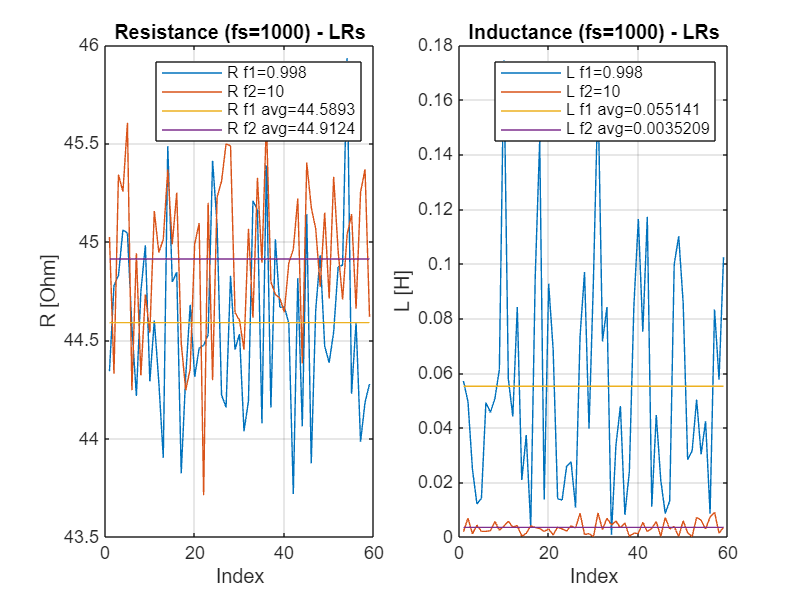

folder = "1Hz\fs1000\";

filenameLRs = folder+"LRs1.csv";
filenameLRp = folder+"LRp.csv";
filenameCRs = folder+"CRs.csv";
filenameCRp = folder+"CRp.csv";


% LR series
T = readmatrix(filenameLRs);
T = T(2:end,:);

fs = T(1,1);
f1 = T(1,2);
f2 = T(1,5);
R1 = abs(T(:,3));
L1 = abs(T(:,4));
R2 = abs(T(:,6));
L2 = abs(T(:,7));
R1_avg = mean(R1)*ones(length(R2),1);
L1_avg = mean(L1)*ones(length(R2),1);
R2_avg = mean(R2)*ones(length(R2),1);
L2_avg = mean(L2)*ones(length(R2),1);

figure()
subplot(1,2,1)
plot(R1);
hold on
plot(R2);
plot(R1_avg);
plot(R2_avg);
hold off
title("Resistance (fs="+num2str(fs)+") - LRs")
grid on
xlabel("Index");
ylabel("R [Ohm]");
legend("R f1="+num2str(f1),"R f2="+num2str(f2), ...
    "R f1 avg="+num2str(R1_avg(1)), ...
    "R f2 avg="+num2str(R2_avg(1)))

subplot(1,2,2)
plot(L1);
hold on
plot(L2);
plot(L1_avg);
plot(L2_avg);
hold off
title("Inductance (fs="+num2str(fs)+") - LRs")
grid on
xlabel("Index");
ylabel("L [H]");
legend("L f1="+num2str(f1),"L f2="+num2str(f2), ...
    "L f1 avg="+num2str(L1_avg(1)), ...
    "L f2 avg="+num2str(L2_avg(1)));

fig = gcf;
print_figures(fig,"LRs_plot",4000,2000,300);

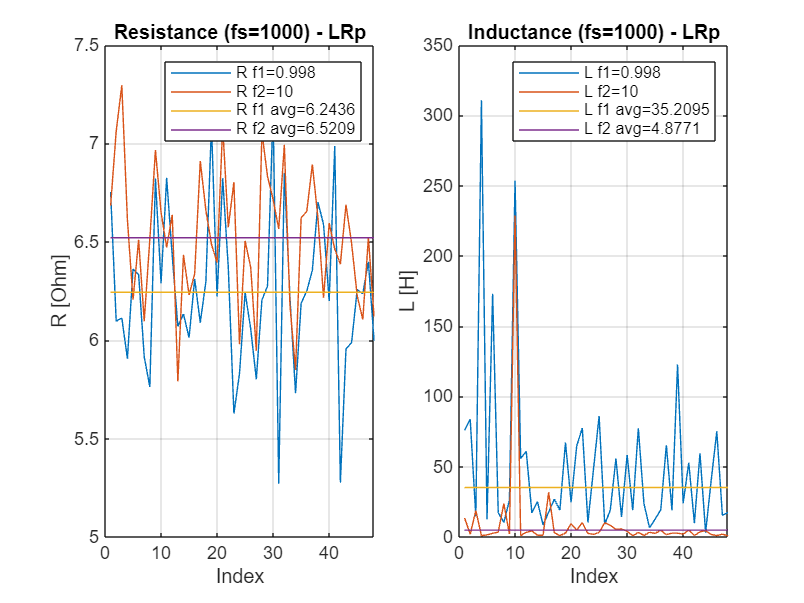


% LR parallel
T = readmatrix(filenameLRp);
T = T(2:end,:);

fs = T(1,1);
f1 = T(1,2);
f2 = T(1,5);
R1 = abs(T(:,3));
L1 = abs(T(:,4));
R2 = abs(T(:,6));
L2 = abs(T(:,7));
R1_avg = mean(R1)*ones(length(R2),1);
L1_avg = mean(L1(L1<100))*ones(length(R2),1);
R2_avg = mean(R2)*ones(length(R2),1);
L2_avg = mean(L2(L2<50))*ones(length(R2),1);

figure()
subplot(1,2,1)
plot(R1);
hold on
plot(R2);
plot(R1_avg);
plot(R2_avg);
hold off
title("Resistance (fs="+num2str(fs)+") - LRp")
grid on
xlabel("Index");
ylabel("R [Ohm]");
legend("R f1="+num2str(f1),"R f2="+num2str(f2),...
    "R f1 avg="+num2str(R1_avg(1)), ...
    "R f2 avg="+num2str(R2_avg(1)))

subplot(1,2,2)
plot(L1);
hold on
plot(L2);
plot(L1_avg);
plot(L2_avg);
hold off
title("Inductance (fs="+num2str(fs)+") - LRp")
grid on
xlabel("Index");
ylabel("L [H]");
legend("L f1="+num2str(f1),"L f2="+num2str(f2), ...
    "L f1 avg="+num2str(L1_avg(1)), ...
    "L f2 avg="+num2str(L2_avg(1)));

fig = gcf;
print_figures(fig,"LRp_plot",4000,2000,300);

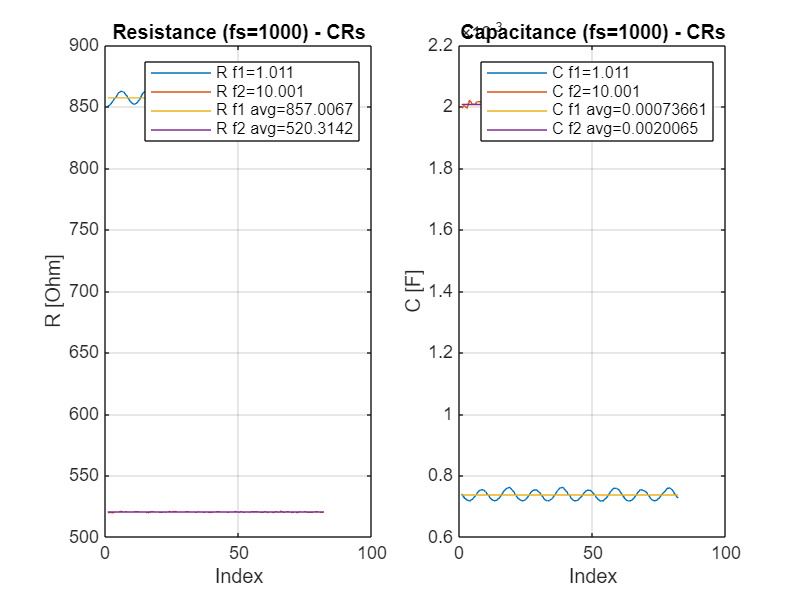



% CR series
T = readmatrix(filenameCRs);
T = T(2:end,:);

fs = T(1,1);
f1 = T(1,2);
f2 = T(1,5);
R1 = abs(T(:,3));
C1 = abs(T(:,4));
R2 = abs(T(:,6));
C2 = abs(T(:,7));
R1_avg = mean(R1)*ones(length(R2),1);
C1_avg = mean(C1)*ones(length(R2),1);
R2_avg = mean(R2)*ones(length(R2),1);
C2_avg = mean(C2)*ones(length(R2),1);

figure()
subplot(1,2,1)
plot(R1);
hold on
plot(R2);
plot(R1_avg);
plot(R2_avg);
hold off
title("Resistance (fs="+num2str(fs)+") - CRs")
grid on
xlabel("Index");
ylabel("R [Ohm]");
legend("R f1="+num2str(f1),"R f2="+num2str(f2),...
        "R f1 avg="+num2str(R1_avg(1)), ...
    "R f2 avg="+num2str(R2_avg(1)))

subplot(1,2,2)
plot(C1);
hold on
plot(C2);
plot(C1_avg);
plot(C2_avg);
hold off
title("Capacitance (fs="+num2str(fs)+") - CRs")
grid on
xlabel("Index");
ylabel("C [F]");
legend("C f1="+num2str(f1),"C f2="+num2str(f2), ...
    "C f1 avg="+num2str(C1_avg(1)), ...
    "C f2 avg="+num2str(C2_avg(1)));

fig = gcf;
print_figures(fig,"CRs_plot",4000,2000,300);

% "1Hz\fs1000\CRs" veletlen a 100uF-os kondival lett mérve XD


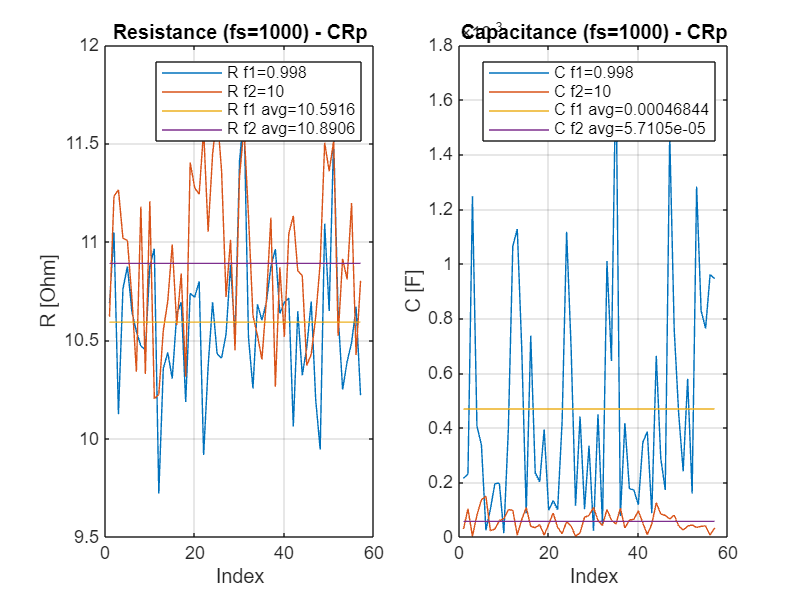


% CR parallel
T = readmatrix(filenameCRp);
T = T(2:end,:);

fs = T(1,1);
f1 = T(1,2);
f2 = T(1,5);
R1 = abs(T(:,3));
C1 = abs(T(:,4));
R2 = abs(T(:,6));
C2 = abs(T(:,7));
R1_avg = mean(R1)*ones(length(R2),1);
C1_avg = mean(C1)*ones(length(R2),1);
R2_avg = mean(R2)*ones(length(R2),1);
C2_avg = mean(C2)*ones(length(R2),1);

figure()
subplot(1,2,1)
plot(R1);
hold on
plot(R2);
plot(R1_avg);
plot(R2_avg);
hold off
title("Resistance (fs="+num2str(fs)+") - CRp")
grid on
xlabel("Index");
ylabel("R [Ohm]");
legend("R f1="+num2str(f1),"R f2="+num2str(f2),...
        "R f1 avg="+num2str(R1_avg(1)), ...
    "R f2 avg="+num2str(R2_avg(1)))

subplot(1,2,2)
plot(C1);
hold on
plot(C2);
plot(C1_avg);
plot(C2_avg);
hold off
title("Capacitance (fs="+num2str(fs)+") - CRp")
grid on
xlabel("Index");
ylabel("C [F]");
legend("C f1="+num2str(f1),"C f2="+num2str(f2), ...
    "C f1 avg="+num2str(C1_avg(1)), ...
    "C f2 avg="+num2str(C2_avg(1)));

fig = gcf;
print_figures(fig,"CRp_plot",4000,2000,300);